# Sign Following Robot with ROS 2 in MATLAB

This example shows you how to use MATLAB® to control a simulated robot running on a separate ROS-based simulator over ROS 2 network. It then shows how to generate a ROS 2 node for the control algorithm and deploy it to a remote device. The example shown here uses ROS 2 and MATLAB for simulation, and MATLAB Coder™ for code generation and deployment.

In this example, you run a MATLAB script that implements a sign-following algorithm and controls the simulated robot to follow a path based on signs in the environment. The algorithm receives the location information and camera information from the simulated robot, which is running in a separate ROS-based simulator. The algorithm detects the color of the sign and sends the velocity commands to turn the robot based on the color. In this example, the algorithm is designed to turn left when robot encounters a blue sign and turn right when robot encounters a green sign. Finally the robot stops when it encounters a red sign.

 To see this example using ROS 1 or Simulink®, see [Sign Following Robot with ROS](docid:ros_ug.mw_351897d0-346d-4fe6-b1aa-86c0a563a6ed).

## Connect to a Robot Simulator

Start a ROS-based simulator for a differential-drive robot and configure the MATLAB® connection with the robot simulator.

To follow along with this example, download a virtual machine using instructions in [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug#mw_9c45a664-ab3d-48a5-a65a-52913b8532b5).

- Start the Ubuntu® virtual machine desktop.

- In the Ubuntu desktop, click the **Gazebo ROS2 Maze** icon to start the Gazebo world built for this example.

- In MATLAB Command Window, set the `ROS_DOMAIN_ID` environment variable to `25` to match the robot simulator ROS bridge settings and run `ros2 topic list `to verify that the topics from the robot simulator are visible in MATLAB.

setenv('ROS_DOMAIN_ID','25')
ros2('topic','list')

/camera/camera_info
/camera/image_raw
/clock
/cmd_vel
/imu
/joint_states
/map_info
/odom
/parameter_events
/rosout
/scan
/tf


## Setup ROS 2 Communication

Create a ROS 2 node using the specified domain ID.

domainID = 25;
n = ros2node("matlab_example_robot",domainID);

Create publishers and subscribers to relay messages to and from the robot simulator over the ROS 2 network. Update the Quality of Service (QoS) policies of publisher and subscriber.  You need subscribers for the image and odometry data. To control the robot, set up a publisher to send velocity commands using the `/cmd_vel` topic.

imgSub = ros2subscriber(n,"/camera/image_raw","sensor_msgs/Image","Reliability","besteffort","Durability","volatile","Depth",5);

odomSub = ros2subscriber(n,"/odom","nav_msgs/Odometry","Reliability","besteffort","Durability","volatile","Depth",5);

[velPub, velMsg] = ros2publisher(n,"/cmd_vel","geometry_msgs/Twist","Reliability","besteffort","Durability","volatile","Depth",5);

Define the image processing color threshold parameters. Each row defines the threshold values for the different colors.

colorThresholds = [100 255 0 55 0 50; ... % Red
                   0 50 50 255 0 50; ...  % Green
                   0 40 0 55 50 255]';    % Blue

## Create Sign Following Controller Using Stateflow® Chart

This example provides an example helper MATLAB Stateflow® chart that takes in the image size, coordinates from processed image, and the robot odometry poses. The chart provides linear and angular velocity to drive the robot based on these inputs.

controller = ExampleHelperSignFollowingControllerChart;
open('ExampleHelperSignFollowingControllerChart');

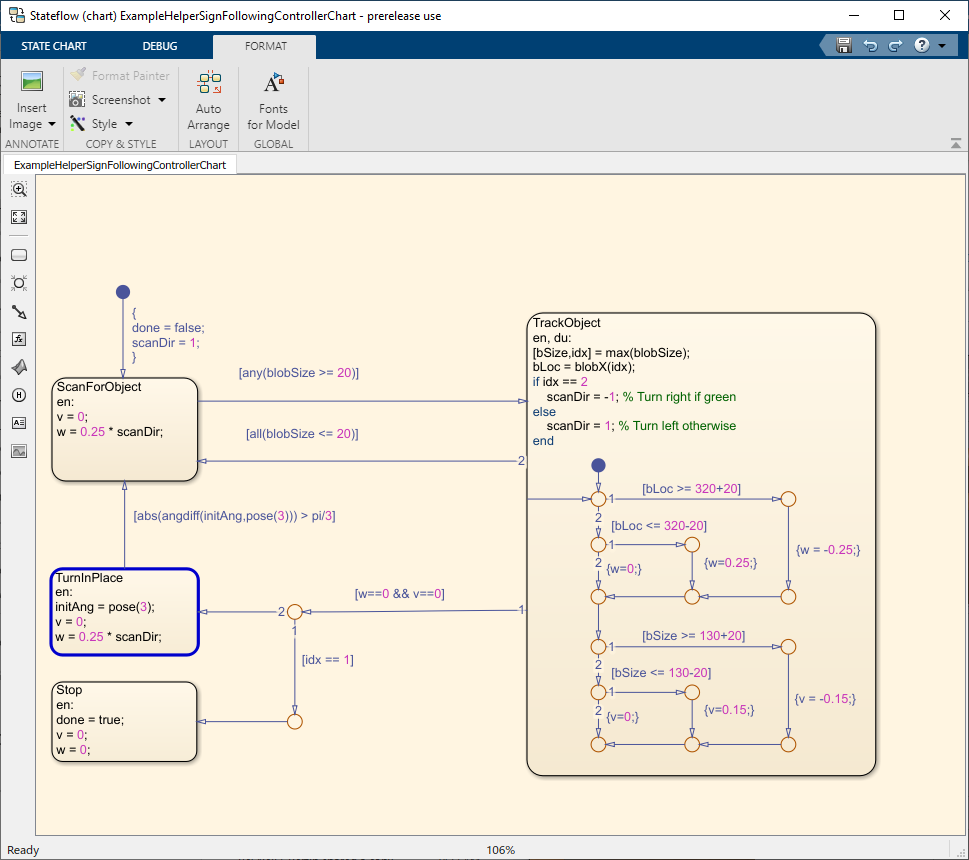

## Run Control Loop

This section runs the controller to receive images and move the robot to follow the sign. The controller does the following steps:

- Gets the latest image and odometry message from the ROS network.

- Runs the algoritm for detecting image features (`ExampleHelperSignFollowingProcessImg`).

- Generates control commands from the Stateflow® chart using `step`.

- Publishes the velocity control commands to the ROS network.

 To visualize the masked image the robot sees, change the value of `doVisualization` variable to `true`.

ExampleHelperSignFollowingSetupPreferences;

% Control the visualization of the mask
doVisualization = false;

r = rateControl(10);
receive(imgSub); % Wait to receive an image message before starting the loop
receive(odomSub);
while(~controller.done)
    % Get latest sensor messages and process them
    imgMsg = imgSub.LatestMessage;
    odomMsg = odomSub.LatestMessage;
    [img,pose] = ExampleHelperSignFollowingProcessMsg(imgMsg, odomMsg);
    
    % Run vision and control functions
    [mask,blobSize,blobX] = ExampleHelperSignFollowingProcessImg(img, colorThresholds);
    step(controller,'blobSize',blobSize,'blobX',blobX,'pose',pose);
    v = controller.v;
    w = controller.w;
    
    % Publish velocity commands
    velMsg.linear.x = v;
    velMsg.angular.z = w;
    send(velPub,velMsg);
    
    % Optionally visualize
    % NOTE: Visualizing data will slow down the execution loop.
    % If you have Computer Vision Toolbox, we recommend using
    % vision.DeployableVideoPlayer instead of imshow.
    if doVisualization
        imshow(mask);
        title(['Linear Vel: ' num2str(v) ' Angular Vel: ' num2str(w)]);
        drawnow('limitrate');
    end
    % Pace the execution loop.
    waitfor(r);
end

You should see the robot moving in the ROS-based robot simulator as shown below.

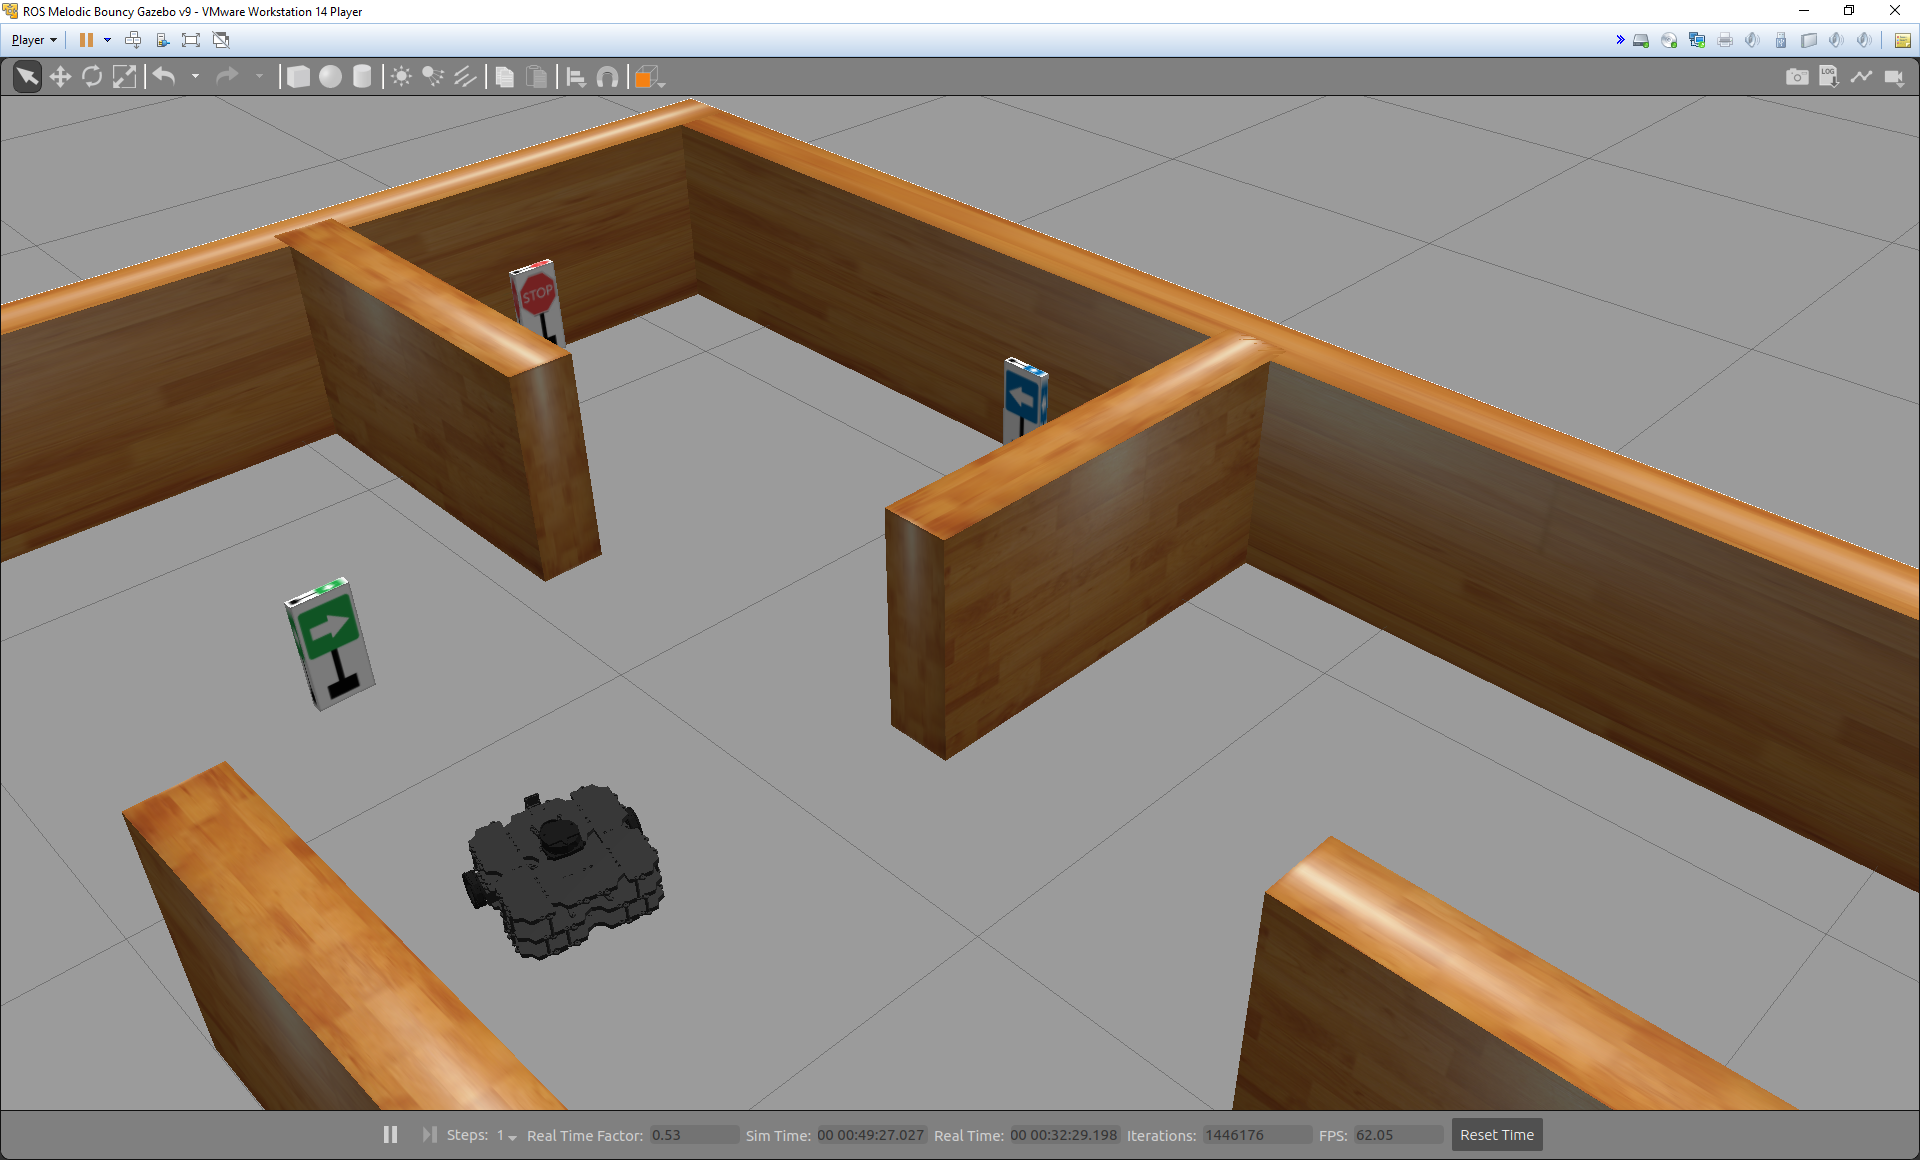

The robot follows the signs and stops at the final STOP sign. Reset the Gazebo scene after simulation using the `/reset_simulation` service. Create a `ros2svcclient` object for the service and use the `call` object function to call the service and reset the Gazebo simulation scene.

gazeboResetClient = ros2svcclient(n,'/reset_simulation','std_srvs/Empty');
call(gazeboResetClient);

## Generate and Deploy ROS 2 Node

After the controller is verified, the next step is to generate a ROS 2 node for the sign following robot algorithm using MATLAB Coder™ and deploy it on the remote Virtual Machine running Gazebo. Deployment enables ROS nodes to run on the remote machines directly, resulting in faster executions. Create a MATLAB Coder configuration object that uses `"Robot Operating System 2 (ROS 2)" `hardware. For the Linux virtual machine for ROS Toolbox, set the following configuration parameters before remote deployment. Note that the actual values might be different for your remote device. Verify them before deployment. Set the build action to '`Build` `and` `Run'` so that the deployed ROS node starts running after code generation.

cfg = coder.config("exe");
cfg.Hardware = coder.hardware("Robot Operating System 2 (ROS 2)");
cfg.Hardware.DeployTo = 'Remote Device';
cfg.Hardware.RemoteDeviceAddress = '192.168.192.129';
cfg.Hardware.RemoteDeviceUsername = 'user';
cfg.Hardware.RemoteDevicePassword = 'password';
cfg.Hardware.BuildAction = "Build and run";

Use `DeploySignFollowingRobotROS2` function that contains the controller algorithm code verified in the previous section. Run the following command to generate the ROS node and deploy the controller. You should see the robot moving in the Gazebo world.

codegen DeploySignFollowingRobotROS2 -config cfg

The robot follows the signs and stops at the final STOP sign. Reset the Gazebo scene after the node executes by calling the `rossvcclient` object, `gazeboResetClient`.

call(gazeboResetClient);

## Rerun the deployed node using `ros2device `

To rerun the deployed ROS node from MATLAB, create a `ros2device` object specifying the `deviceAddress,` `username,` and `password` values of the Virtual Machine running Gazebo. This establishes an SSH connection between the ROS device and MATLAB. Check the available nodes on the connected remote device. Verify that the deployed ROS node, `DeploySignFollowingRobotROS2`, exists.  

gazeboVMDevice = ros2device('192.168.192.129','user','password');
gazeboVMDevice.AvailableNodes

 Run the ROS node deployed on the remote device using `runNode` function.

runNode(gazeboVMDevice,'DeploySignFollowingRobotROS2')

*Copyright 2019 The MathWorks, Inc.*